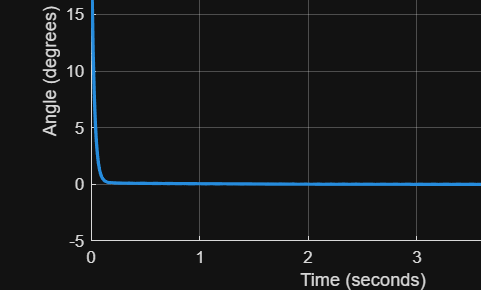

clc;
clear;
close all;


s = tf('s');

% Plant (inverted pendulum approximation)
G = 1/(s^2 - 10);

% PID gains
Kp = 50;
Ki = 0.5;
Kd = 40;

% PID controller
C = pid(Kp, Ki, Kd);

% Closed-loop system
T = feedback(C*G,1);

% Convert to state-space
sys = ss(T);

% Time vector
t = 0:0.01:5;

% Get number of states automatically
n = size(sys.A,1);

% Initial conditions
x0 = zeros(n,1);
x0(1) = 5;     % 5 degree initial tilt

% Simulate initial response
[y,t] = initial(sys,x0,t);

% Plot
figure;
plot(t,y,'LineWidth',2);
grid on;

xlabel('Time (seconds)');
ylabel('Angle (degrees)');
title('Initial Tilt Recovery of Self-Balancing Robot');